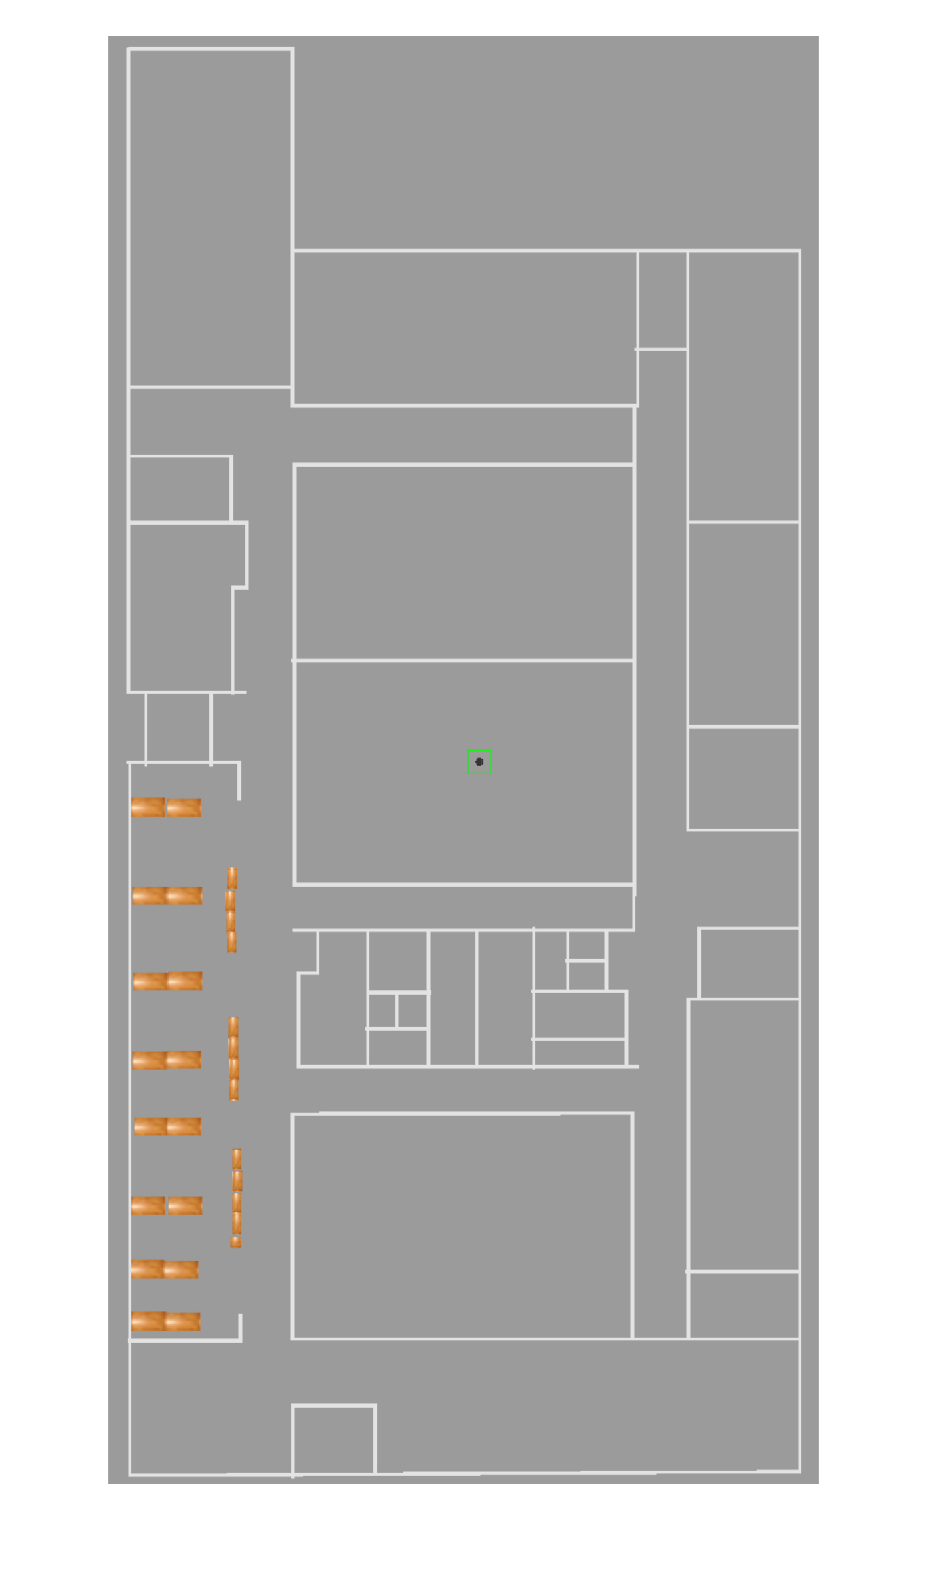

clear, close all;

% Load Color Image
map_color = imread('World_Simple.png');

figure(1), imshow(map_color)

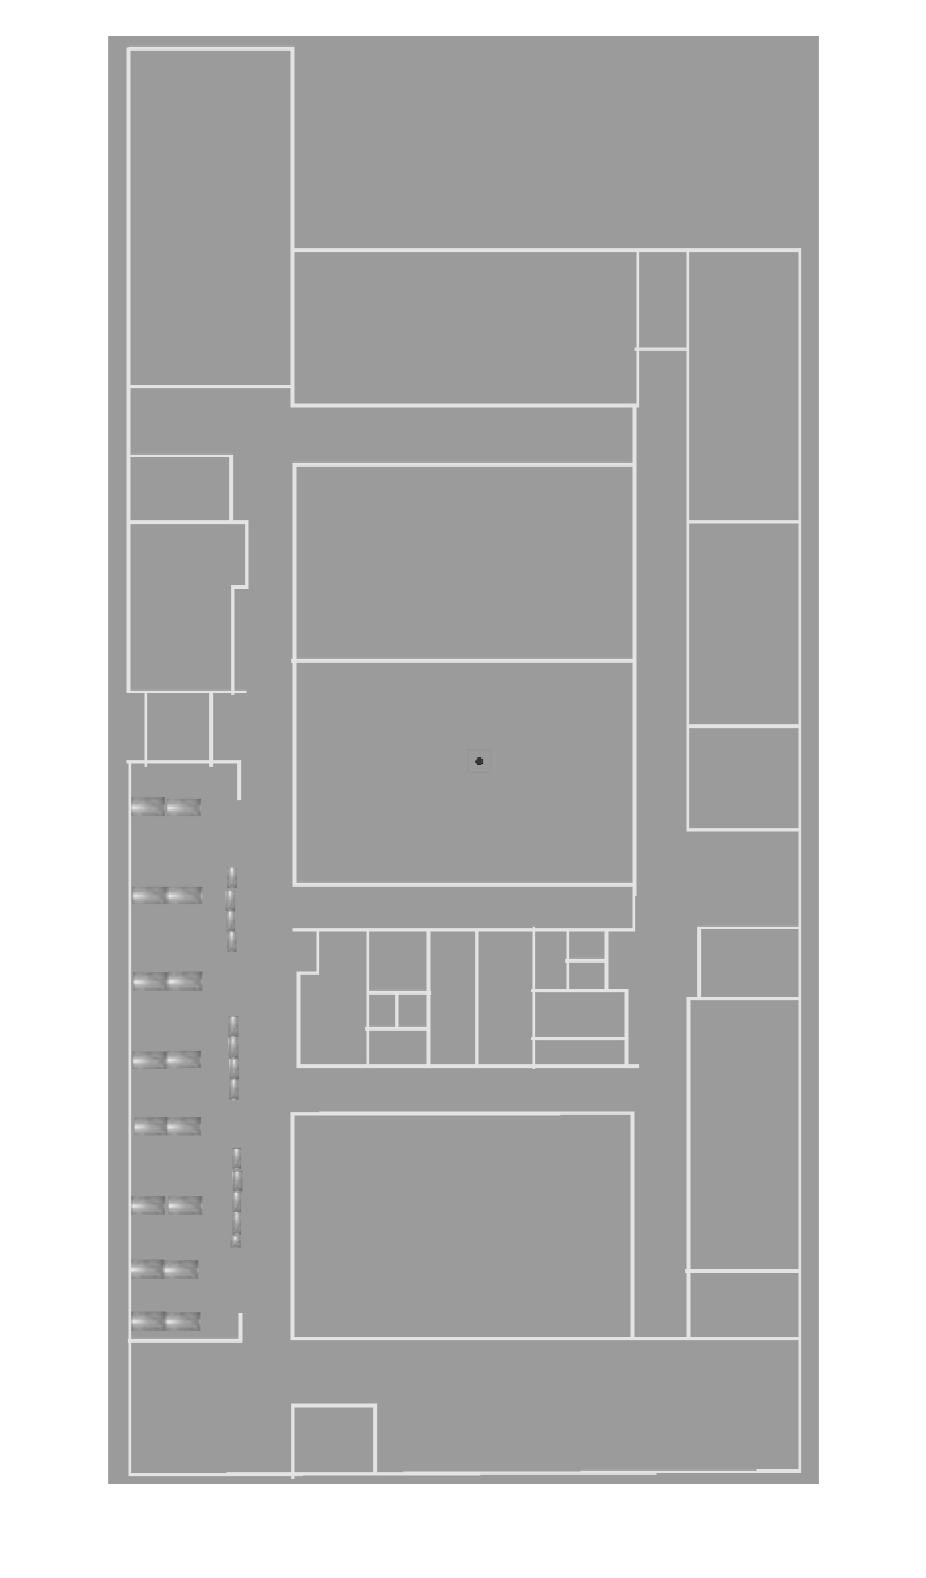


% Convert to Grayscale
map_bw = rgb2gray(map_color);
imshow(map_bw)


% Calculating Mean Pixel Value
mean_value = mean(map_bw(:));

% Converting the image to BW
%zero_matrix=zeros(size(map_bw)); %Making empty matrix with the size of the original picture (all black)

%above_mean=find(map_bw>mean_value); %Finds all values above the mean and saves the index/position to "abovemean"

im_binary = map_bw>mean_value;

%zero_matrix(above_mean)=255; %Sets all the positions from "abovemean" to 255 in the zero matrix, thereby making them black
%% 

figure(); 
imshow(zero_matrix); %Shows the binary image

im_complement = imcomplement(zero_matrix);
imshow(im_complement)



im_binary = im_complement==1;


imshow(im_binary)